dir = '/home/saturn/Project-ABG/ABG_classification/data/pngs';
[trainingIMDS, validationIMDS, testIMDS] = getOrginalDataSplits(dir,2,"test");
% Get Data

% Load network
net = alexnet;
net = net.net

net =   SeriesNetwork with properties:

         Layers: [24×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


inputSize = net.Layers(1).InputSize;

## % Resize the data

%resize datastore to network input size
train_audIMDS = augmentedImageDatastore(inputSize, trainingIMDS);
validation_audIMDS = augmentedImageDatastore(inputSize, validationIMDS);
test_audIMDS = augmentedImageDatastore(inputSize, testIMDS);

% Important datastores have been resized to fit specified for
% the model
train_audIMDS;
validation_audIMDS;
test_audIMDS;
% end of data split


% layer + features
layer = "pool5";
featuresTrain = activations(net,train_audIMDS,layer,'ExecutionEnvironment',"auto");
featuresTest = activations(net,test_audIMDS,layer,'ExecutionEnvironment',"auto");
whos featuresTrain

  Name               Size                       Bytes  Class     Attributes

  featuresTrain      2x2x432x7041            48667392  single              




featuresTrain = squeeze(mean(featuresTrain,[1 2]))';
featuresTest = squeeze(mean(featuresTest,[1 2]))';
whos featuresTrain

  Name                  Size                Bytes  Class     Attributes

  featuresTrain      7041x432            12166848  single              



### % SVM templates 

t1 = templateSVM( ...
     'Standardize',true, ...
     'KernelFunction','linear', ...
     'BoxConstraint',0.699,...
     'KernelScale',13.541...
     );

t2 = templateSVM( ...
    "BoxConstraint",1.4842,...
    'KernelScale',31.659,...
     'KernelFunction','polynomial', ...
     'PolynomialOrder',2, ...
     'Standardize',true ...
     );

t3 = templateSVM( ...
    'BoxConstraint',2.1731,...
    'KernelScale','auto',...
     'Standardize',false, ...
     'KernelFunction','rbf' ...
     );

t4 = templateSVM( ...
    'BoxConstraint',2.0862,...
    'KernelScale','auto',...
     'Standardize',false, ...
     'KernelFunction','gaussian' ...
     );

### % Classify, Predict, Confusion Matrices and F-Scores

accuracy = 0.6600

fScore =     0.7755    0.6866    0.6600    0.4412


avg_f_score = 0.6408

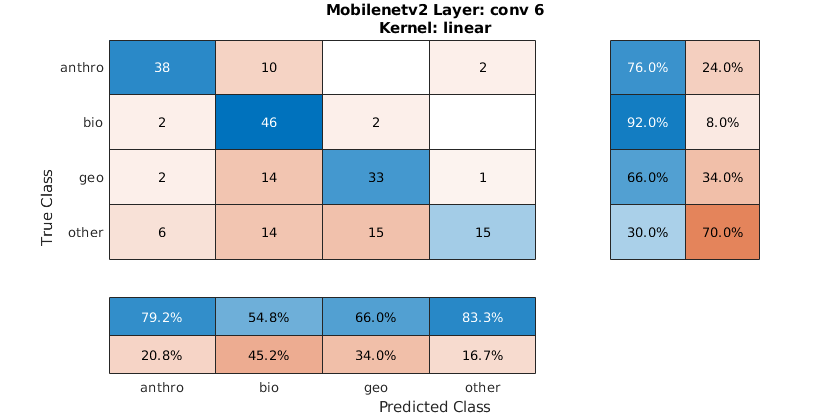

accuracy = 0.6900

fScore =     0.8081    0.7077    0.6800    0.5070


avg_f_score = 0.6757

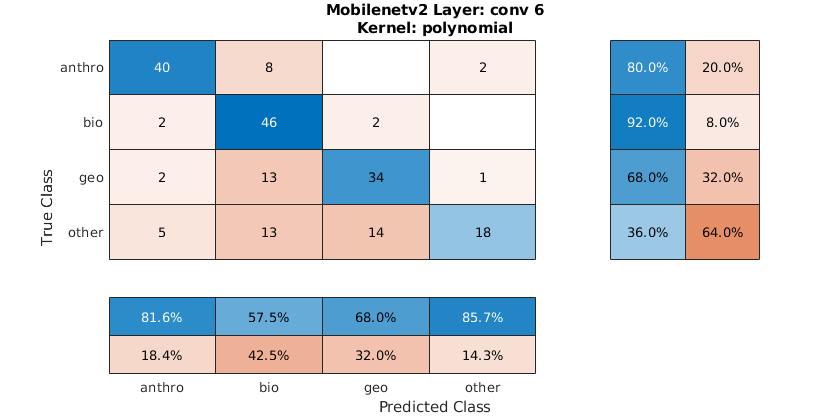

accuracy = 0.7150

fScore =     0.8000    0.7143    0.7619    0.5217


avg_f_score = 0.6995

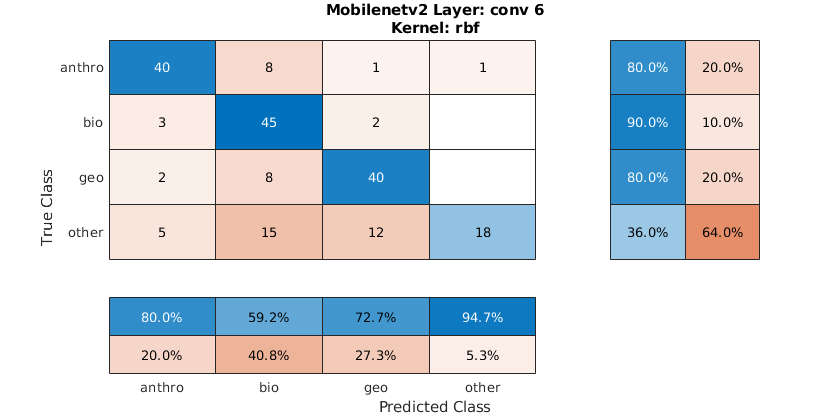

accuracy = 0.7000

fScore =     0.8081    0.7077    0.7129    0.5143


avg_f_score = 0.6857

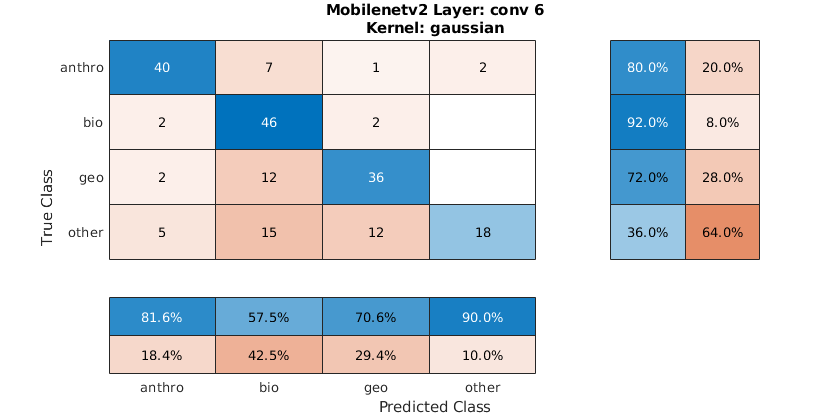

template = {t1,t2,t3,t4};
kernel = ["linear" "polynomial" "rbf" "gaussian"];
layer_name = strrep(layer,'_',' ');

for n=1:size(template,2)
    classifier = fitcecoc( ...
        featuresTrain, ...
        trainingIMDS.Labels, ...
        'Learners',template(n), ...
        'Options',statset('UseParallel',true) ...
        );
    
    
    YPred = predict(classifier,featuresTest);
    accuracy = mean(YPred == testIMDS.Labels);
    
    % Displaying confusion chart
    fig = figure;
    fig_Position = fig.Position;
    fig_Position(3) = fig_Position(3)*1.5;
    fig.Position = fig_Position;
    cm = confusionchart(testIMDS.Labels,YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');
    
    t = ["Mobilenetv2 Layer: "+layer_name,"Kernel: "+kernel(n)];
title(cm,t)
    
    % Calculating fScore and avg_f_score
    cm1 = cm.NormalizedValues;
    
    for i = 1:size(cm1,1)
        precision(i) = cm1(i,i)/sum(cm1(i,:));
    end
    
    for i = 1:size(cm1,1)
        recall(i) = cm1(i,i)/sum(cm1(:,i));
    end
    
    for i = 1:size(precision,2)
        fScore(i) = (2 * (precision(i) * recall(i)) / (precision(i) + recall(i)));
    end
    
    % Displaying results
    accuracy
    fScore
    avg_f_score = sum(fScore)/numel(fScore)
    filename = "svm_data/t"+num2str(n)+"_mobilenetv2_"+layer_name+"_s2";
    save(filename, 'accuracy','fScore','avg_f_score');
    print(fig,"t"+num2str(n)+"_cm_mobilenetv2",'-dpng');
    
end